# Inicia TODO el CoBot para real

ur = urRTDEClient('192.168.1.10','CobotName','universalUR5e') %Conectamos ROS de matlab con el cobot

ur =   urRTDEClient with properties:

            CobotName: 'universalUR5e'
       URControllerIP: '192.168.1.10'
    ControllerVersion: '5.11.10.0'
        RTDEFrequency: 125
    ConnectionTimeOut: 10
        RigidBodyTree: [1×1 rigidBodyTree]


jointAngles = readJointConfiguration(ur) %Lee los angulos del brazo

jointAngles =     5.0665   -1.9305   -1.1803   -1.6016    1.5708   -2.9659


%defase_Robot = 0; %Ve a Y positivo (Lado del cable)
defase_Robot = pi; %Ve a Y negativo (Otro lado del cable)

# Limpia la variable de UR en caso de error

clear ur

# Mover al cobot por coordenadas cartesianas

x = 0;
y = 0.75;
z = 0.35;
angulo_Gripper = 90;

coci = car2pol(x,y,z)

coci =     0.7500    1.5708    0.3500


jointAngles = MoverRobot(coci,angulo_Gripper,defase_Robot,jointAngles,ur);

# Mover al cobot por coordenadas cilindricas

%Limites de los sliders
theta_min = -3*pi/4;
theta_max = 3*pi/4;
angulogripmin = -pi;
angulogripmax = pi;

r =0.455

r = 0.4550

theta = 1.72

theta = 1.7200

h_deseada = 0.29

h_deseada = 0.2900

angulo_Gripper = -1.5415926535898

angulo_Gripper = -1.5416


h_posible = min(h_deseada,sqrt(0.91^2-r^2)) 

h_posible = 0.2900

% coordenadas_cilindricas(r,theta,h)
coci = [r,theta,h_posible];
jointAngles = MoverRobot(coci,angulo_Gripper,defase_Robot,jointAngles,ur);

# Posicion inicial de Robocup ARM Challenge

jointWaypoints = [90 -90 0 0 -90 0]*pi/180

jointWaypoints =     1.5708   -1.5708         0         0   -1.5708         0


[~,~] = sendJointConfigurationAndWait(ur,jointWaypoints,'EndTime',10)

result = logical
   1


state = 'Succeeded'

# Posicion inicial de Cobot

jointWaypoints = [0 -90 0 -90 0 0]*pi/180

jointWaypoints =          0   -1.5708         0   -1.5708         0         0


[~,~] = sendJointConfigurationAndWait(ur,jointWaypoints,'EndTime',10)

# Toma una foto

fotosw() %La foto actual es la computern.jpg

# Creacion de objeto virtual (Prueba)

robot = loadrobot("universalUR5e");
configuraciones = robot.homeConfiguration;

# Uso de objeto virtual (Prueba)

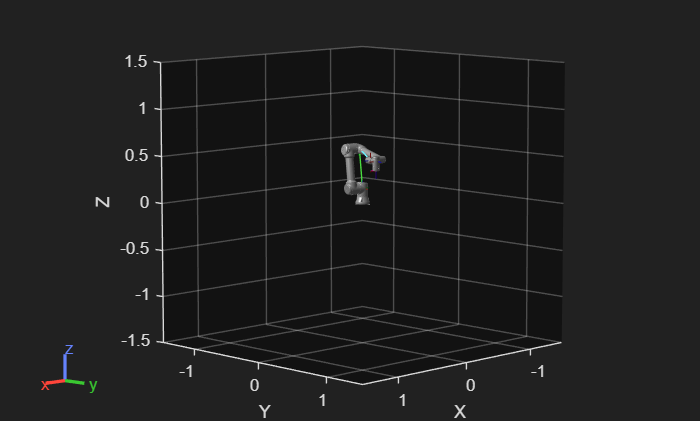

ans =   Axes (Primary) with properties:

             XLim: [-1.5000 1.5000]
             YLim: [-1.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


for n = 1:6
    configuraciones(n).JointPosition = jointAngles(n);
end
show(robot,configuraciones)